A1_heq0 = load('/home/jmenard/S2019_rpt_sociodynamics_data/sim_1900to2200_heq0.mat');
A1_heq1 = load('/home/jmenard/S2019_rpt_sociodynamics_data/sim_1900to2200_heq1.mat');

all_results_heq0 = A1_heq0.all_results;
all_results_heq1 = A1_heq1.all_results;


temperature_vals_heq0 = all_results_heq0.T;
temperature_vals_heq1 = all_results_heq1.T;
bline_params_results = all_results.blineParams;

median_vals_heq0 = quantile(temperature_vals_heq0', 0.5);
bot_five_heq0    = quantile(temperature_vals_heq0', 0.05);
top_five_heq0    = quantile(temperature_vals_heq0', 0.95);

median_vals_heq1 = quantile(temperature_vals_heq1', 0.5);
bot_five_heq1    = quantile(temperature_vals_heq1', 0.05);
top_five_heq1    = quantile(temperature_vals_heq1', 0.95);

clf
plot(all_results.pre2014(:,1), all_results.pre2014(:,end))
%plot(test_1751to2014(:,1), test_1751to2014(:,end))
hold on
%plot(tspan, avg_(:,end))
xlim([1900,max(tspan)])
ylim([0,8])
size(temperature_vals)

ans =         1861         100


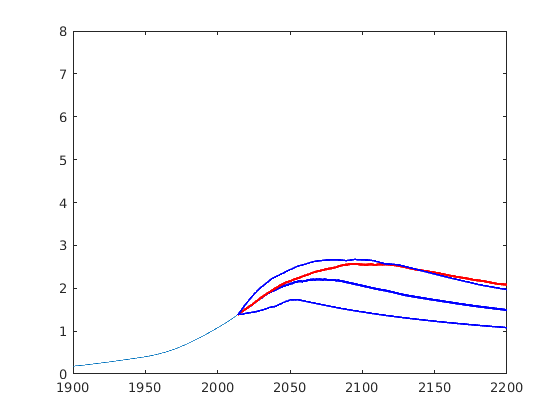


%plot(tspan, bline_params_results(:,end))
plot(tspan, median_vals_heq0, 'LineWidth', 2,'Color','b')
plot(tspan, median_vals_heq1, 'LineWidth', 2,'Color','r')

plot(tspan, top_five_heq0, 'LineWidth', 1.5, 'Color','b')
alpha(0.15);
plot(tspan, bot_five_heq0, 'LineWidth', 1.5, 'Color','b')

alpha(0.15);
%legend("pre2014","median", "top5", "bot5")

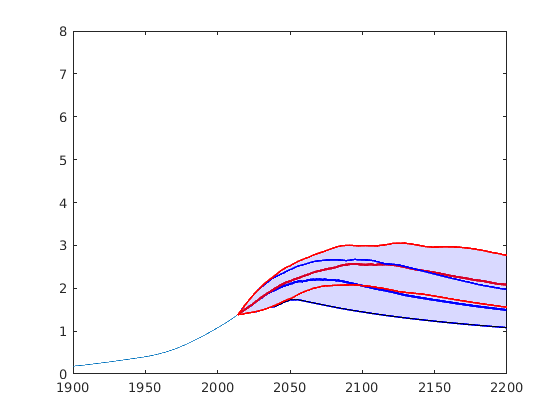

x2 = [tspan, fliplr(tspan)];
inBetween_heq0 = [bot_five_heq0, fliplr(top_five_heq1)];
fill(x2, inBetween_heq0, 'b');
alpha(0.1);


plot(tspan, top_five_heq1, 'LineWidth', 1.5, 'Color','r')
alpha(0.15);
plot(tspan, bot_five_heq1, 'LineWidth', 1.5, 'Color','r')
alpha(0.15);

%legend("pre2014","median", "top5", "bot5")

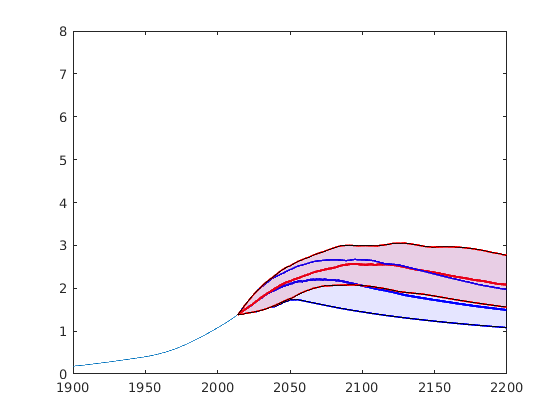

x2 = [tspan, fliplr(tspan)];
inBetween_heq1 = [bot_five_heq1, fliplr(top_five_heq1)];
fill(x2, inBetween_heq1, 'r');
alpha(0.1);

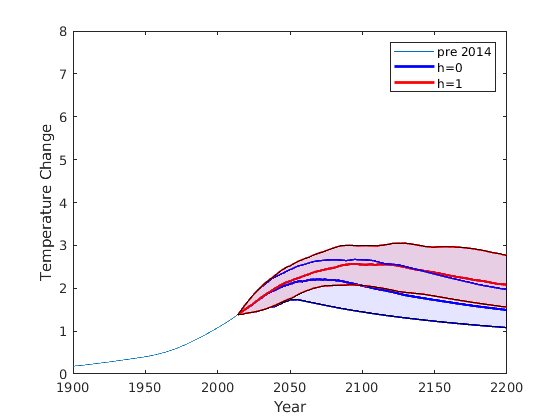

xlabel('Year')
ylabel('Temperature Change')
legend("pre 2014","h=0", "h=1")